# Project 1

## Theoretical Validation

clear; clc;

### General Cases

e = [0;0;0];
I = [3 0 0; 0 2 0; 0 0 1];
b3_hat = [0;0;1];

#### Null Case

w_0 = [0;0;0];
w_0_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_null = runModel(I, g, w_0, e, b3_hat);

e_null = out_null.angle_out(end,:)

e_null =      0     0     0


w_null = out_null.omega(end,:)

w_0_null =      0     0     0


w_body_null = out_null.omega(end,:)

w_0_body_null =      0     0     0


h_null = out_null.ang_mom(end,:)

h_null =      0     0     0


h_body_null = out_null.ang_mom_body(end,:)

h_body_null =      0     0     0


#### Constant Rotation Case 1

w_0 = [1;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_constant1 = runModel(I, g, w_0, e, b3_hat);

e_constant1 = out_constant1.angle_out(out_constant1.tout == 2, :)

e_constant1 =          0    1.9900         0


w_constant1 = out_constant1.omega(out_constant1.tout == 2, :)

w_0_constant1 =      1     0     0


w_body_constant1 = out_constant1.omega_body(out_constant1.tout == 2, :)

w_0_body_constant1 =      1     0     0


h_constant1 = out_constant1.ang_mom(out_constant1.tout == 2, :)

h_constant1 =      3     0     0


h_body_constant1 = out_constant1.ang_mom_body(out_constant1.tout == 2, :)

h_body_constant1 =      3     0     0


#### Constant Rotation Case 2

w_0 = [0;1;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_constant2 = runModel(I, g, w_0, e, b3_hat);

e_constant2 = out_constant2.angle_out(out_constant2.tout == 2, :)

e_constant2 =     1.5708    1.9900   -1.5708


w_constant2 = out_constant2.omega(out_constant2.tout == 2, :)

w_0_constant2 =      0     1     0


w_body_constant2 = out_constant2.omega_body(out_constant2.tout == 2, :)

w_0_body_constant2 =      0     1     0


h_constant2 = out_constant2.ang_mom(out_constant2.tout == 2, :)

h_constant2 =      0     2     0


h_body_constant2 = out_constant2.ang_mom_body(out_constant2.tout == 2, :)

h_body_constant2 =      0     2     0


#### Constant Rotation Case 3

w_0 = [0;0;1];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_constant3 = runModel(I, g, w_0, e, b3_hat);


e_constant3 = out_constant3.angle_out(out_constant3.tout == 2, :)

e_constant3 =     1.9900         0         0


w_constant3 = out_constant3.omega(out_constant3.tout == 2, :)

w_0_constant3 =      0     0     1


w_body_constant3 = out_constant3.omega_body(out_constant3.tout == 2, :)

w_0_body_constant3 =      0     0     1


h_constant3 = out_constant3.ang_mom(out_constant3.tout == 2, :)

h_constant3 =      0     0     1


h_body_constant3 = out_constant3.ang_mom_body(out_constant3.tout == 2, :)

h_body_constant3 =      0     0     1


#### Constant Torque Case 1

w_0 = [0;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [1;0;0];

out_torque1 = runModel(I, g, w_0, e, b3_hat);

e_torque1 = out_torque1.angle_out(out_torque1.tout == 3, :)

e_torque1 =          0    1.4900         0


w_torque1 = out_torque1.omega(out_torque1.tout == 3, :)

w_0_torque1 =     0.9967         0         0


w_body_torque1 = out_torque1.omega_body(out_torque1.tout == 3, :)

w_0_body_torque1 =     0.9967         0         0


h_torque1 = out_torque1.ang_mom(out_torque1.tout == 3, :)

h_torque1 =     2.9900         0         0


h_body_torque1 = out_torque1.ang_mom_body(out_torque1.tout == 3, :)

h_body_torque1 =     2.9900         0         0


#### Constant Torque Case 2

w_0 = [0;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;1;0];

out_torque2 = runModel(I, g, w_0, e, b3_hat);

e_torque2 = out_torque2.angle_out(out_torque2.tout == 3, :)

e_torque2 =     1.5708    2.2350   -1.5708


w_torque2 = out_torque2.omega(out_torque2.tout == 3, :)

w_0_torque2 =          0    1.4950         0


w_body_torque2 = out_torque2.omega_body(out_torque2.tout == 3, :)

w_0_body_torque2 =          0    1.4950         0


h_torque2 = out_torque2.ang_mom(out_torque2.tout == 3, :)

h_torque2 =          0    2.9900         0


h_body_torque2 = out_torque2.ang_mom_body(out_torque2.tout == 3, :)

h_body_torque2 =          0    2.9900         0


#### Constant Torque Case 3

w_0 = [0;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;1];

out_torque3 = runModel(I, g, w_0, e, b3_hat);


e_torque3 = [2*pi, 0, 0] + out_torque3.angle_out(out_torque3.tout == 3, :)

e_torque3 =     4.4701         0         0


w_torque3 = out_torque3.omega(out_torque3.tout == 3, :)

w_0_torque3 =          0         0    2.9900


w_body_torque3 = out_torque3.omega_body(out_torque3.tout == 3, :)

w_0_body_torque3 =          0         0    2.9900


h_torque3 = out_torque3.ang_mom(out_torque3.tout == 3, :)

h_torque3 =          0         0    2.9900


h_body_torque3 = out_torque3.ang_mom_body(out_torque3.tout == 3, :)

h_body_torque3 =          0         0    2.9900


### Specific Cases

e = [0;0;0];
b3_hat = [0;0;1];

#### Isoinertial Case

I = [1 0 0; 0 1 0; 0 0 1];
w_0 = [1;0;0];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;2;0];

out_iso = runModel(I, g, w_0, e, b3_hat);

e_iso = out_iso.angle_out(out_iso.tout == 2, :);
w_iso = out_iso.omega(out_iso.tout == 2, :)

w_iso =     1.0000    4.0000         0


w_body_iso = out_iso.omega_body(out_iso.tout == 2, :);
h_iso = out_iso.ang_mom(out_iso.tout == 2, :)

h_iso =     1.0000    4.0000         0


h_body_iso = out_iso.ang_mom_body(out_iso.tout == 2, :);

#### Axisymmetric Prolate Case

I_t = 2;
I_a = 10;
I = [I_t 0 0; 0 I_t 0; 0 0 I_a];
w_0 = [0.5;0.5;1];
w_o_body = w_0;
h = I*w_0;
h_body = h;
g = [0;0;0];

out_axypro = runModel(I, g, w_0, e, b3_hat);

e_axypro = out_axypro.angle_out(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);
w_axypro = out_axypro.omega(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :)

w_axypro =     0.5016    0.4984    1.0000


w_body_axypro = out_axypro.omega_body(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);
h_axypro = out_axypro.ang_mom(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :)

h_axypro =     1.0032    0.9968   10.0000


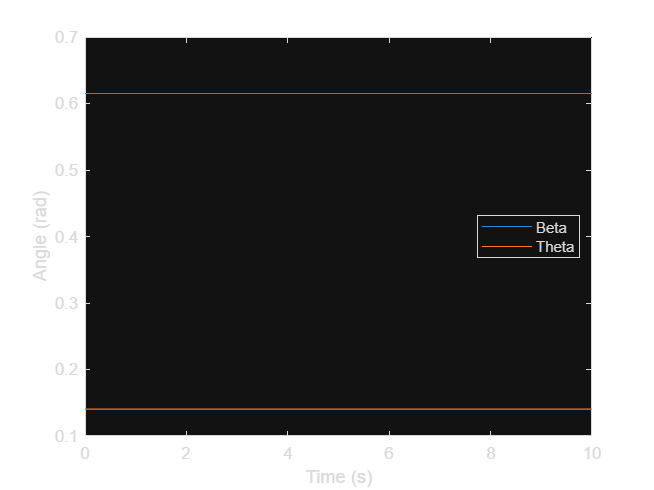

h_body_axypro = out_axypro.ang_mom_body(abs(out_axypro.tout - pi/2) == min(abs(out_axypro.tout - pi/2)), :);

beta = acos(out_axypro.omega(:,3)./vecnorm(out_axypro.omega, 2, 2));
theta = acos(out_axypro.ang_mom(:,3)./vecnorm(out_axypro.ang_mom, 2, 2));

figure
plot(out_axypro.tout, beta, out_axypro.tout, theta)
xlabel("Time (s)")
ylabel("Angle (rad)")
legend("Beta", "Theta", "Location", "best")

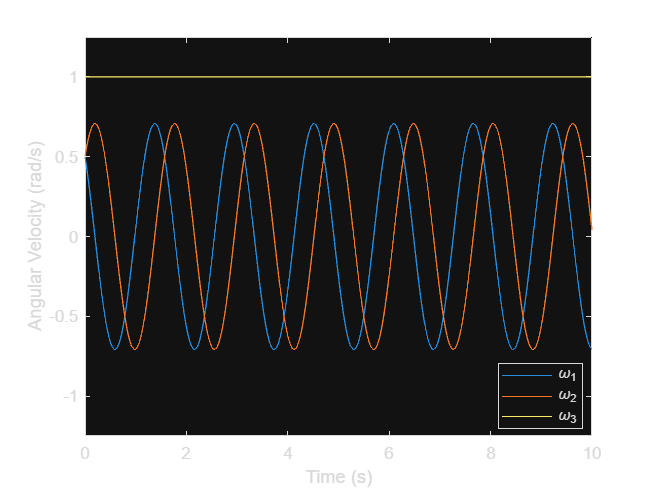


figure
plot(out_axypro.tout, out_axypro.omega(:,1), out_axypro.tout, out_axypro.omega(:,2), out_axypro.tout, out_axypro.omega(:,3))
ylim([-1.25, 1.25])
xlabel("Time (s)")
ylabel("Angular Velocity (rad/s)")
legend("\omega_1", "\omega_2", "\omega_3", "Location", "best")